clc; close all; clear all;

%% =============================================
%  PARAMETERS
%% =============================================
p.m = 0.1;
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;
J_true = 8.9432e-4;

%% =============================================
%  LOAD MEASURED DATA
%% =============================================
data = readmatrix('data.csv');

Ts        = data(2,1) - data(1,1);
time_meas = data(1:300, 1);

angle_20 = deg2rad(data(1:300, 3));
angle_50 = deg2rad(data(1:300, 6));
angle_80 = deg2rad(data(1:300, 9));

pwm_vals   = [20, 50, 80];
meas_theta = {angle_20, angle_50, angle_80};
colors     = {'b', 'r', [0.1 0.6 0.1]};

t_meas = time_meas;
Ts_sim = 0.001;
t_sim  = (t_meas(1) : Ts_sim : t_meas(end))';

%% =============================================
%  SCRIPT 1 — NO FRICTION MODEL (b = 0)
%  Uses FFT-estimated frequency per PWM
%% =============================================
alpha = p.m + p.M - (p.m^2 * p.l^2) / (J_true + p.m * p.l^2);
beta  = (J_true + p.m * p.l^2) - (p.m^2 * p.l^2) / (p.m + p.M);

A_nf = [0 1 0 0;
        0, 0, -(p.m^2*p.l^2*p.g)/(alpha*(J_true+p.m*p.l^2)), 0;
        0 0 0 1;
        0, 0,  (p.m*p.g*p.l)/beta, 0];
B_nf = [0; 1/alpha; 0; -(p.m*p.l)/beta*(p.m+p.M)];
C_mat = [1 0 0 0; 0 0 1 0];
D_mat = [0; 0];
sys_nf = ss(A_nf, B_nf, C_mat, D_mat);

fprintf('====== Script 1: No-Friction (b=0) ======\n');

====== Script 1: No-Friction (b=0) ======


fprintf('%-10s %-15s %-15s\n', 'PWM', 'Freq (Hz)', 'RMSE (deg)');

PWM        Freq (Hz)       RMSE (deg)     


fprintf('%s\n', repmat('-',1,42));

------------------------------------------



omega_per_pwm = zeros(1,3);  % store for reuse in Script 2

figure('Name','Script 1 — No-Friction Model vs Measured');
for i = 1:3
    N      = length(t_meas);
    Y_fft  = abs(fft(meas_theta{i}));
    Y_fft(1) = 0;
    half_N = floor(N/2);
    f_vec  = (0:half_N-1) / (N * Ts);
    [~, idx] = max(Y_fft(1:half_N));
    omega_est = 2 * pi * f_vec(idx);
    omega_per_pwm(i) = omega_est;

    u_sine      = sin(omega_est * t_sim);
    y_nf        = lsim(sys_nf, u_sine, t_sim);
    theta_unit  = interp1(t_sim, y_nf(:,2), t_meas);
    scale       = max(abs(meas_theta{i})) / max(abs(theta_unit));
    theta_model = scale * theta_unit;

    rmse = rad2deg(sqrt(mean((meas_theta{i} - theta_model).^2)));
    fprintf('%-10d %-15.4f %-15.4f\n', pwm_vals(i), f_vec(idx), rmse);

    subplot(3,1,i);
    plot(t_meas, rad2deg(meas_theta{i}), 'k',  'LineWidth', 2.0, 'DisplayName', 'Measured'); hold on;
    plot(t_meas, rad2deg(theta_model),   '--', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Model (b=0), RMSE=%.4f deg', rmse));
    title(sprintf('Pendulum Angle \\theta — PWM = %d', pwm_vals(i)));
    xlabel('Time (s)'); ylabel('\theta (deg)');
    legend('Location','best'); grid on;
    ylim([-200 200]);
end

20         1.3333          12.6759        
50         0.3333          23.5695        
80         0.3333          114.9719       


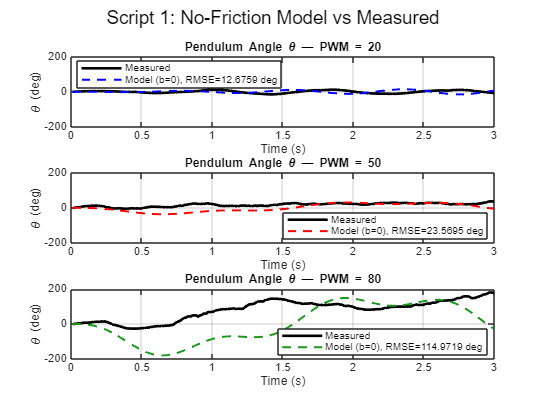

sgtitle('Script 1: No-Friction Model vs Measured');


%% =============================================
%  SCRIPT 2 — OPTIMIZE FRICTION b
%  FIX 1: Use same FFT-estimated omega (not hardcoded)
%  FIX 2: Use sine input (not square wave)
%  FIX 3: Optimize over ALL 3 PWM datasets jointly
%% =============================================

% Use average omega across all PWMs for a single consistent drive input
omega_drive = mean(omega_per_pwm);
fprintf('\nUsing mean omega for optimization: %.4f rad/s (%.4f Hz)\n', ...
        omega_drive, omega_drive/(2*pi));


Using mean omega for optimization: 4.1888 rad/s (0.6667 Hz)



b_guess = 0.01;
options = optimset('Display','iter','TolX',1e-6,'TolFun',1e-6,'MaxIter',1000);

best_b = fminsearch(@(b) cost_function_b_joint(b, p, J_true, t_meas, ...
                    meas_theta, Ts_sim, omega_drive), b_guess, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1          2.61948         
     1            2          2.61924         initial simplex
     2            4          2.61875         expand
     3            6          2.61781         expand
     4            8          2.61598         expand
     5           10          2.61259         expand
     6           12          2.60663         expand
     7           14          2.59783         expand
     8           16          2.57453         expand
     9           18          2.55262         expand
    10           20          2.55148         reflect
    11           22          2.55004         contract inside
    12           24          2.55004         contract inside
    13           26          2.55004         contract inside
    14           28          2.55002         contract inside
    15           30          2.55002         contract inside
    16           32          2.55002         contract inside
 


fprintf('\n====== Optimization Results ======\n');


====== Optimization Results ======


fprintf('Optimized Friction b : %.6f\n', best_b);

Optimized Friction b : 0.335442



%% =============================================
%  BUILD OPTIMIZED MODEL
%% =============================================
M_total = p.m + p.M;
L_p     = J_true + p.m * p.l^2;
det_val = M_total * L_p - (p.m * p.l)^2;

A_opt = [0 1 0 0;
         0, -best_b*L_p/det_val,       -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  best_b*p.m*p.l/det_val,    (p.m*p.g*p.l*M_total)/det_val, 0];
B_opt = [0; L_p/det_val; 0; -p.m*p.l/det_val];
sys_opt = ss(A_opt, B_opt, C_mat, D_mat);

%% =============================================
%  PLOT: FAIR SIDE-BY-SIDE COMPARISON
%  Both models use identical sine input per PWM
%% =============================================
fprintf('\n====== RMSE Summary (Fair Comparison) ======\n');


====== RMSE Summary (Fair Comparison) ======


fprintf('%-10s %-20s %-20s\n', 'PWM', 'RMSE b=0 (deg)', 'RMSE opt (deg)');

PWM        RMSE b=0 (deg)       RMSE opt (deg)      


fprintf('%s\n', repmat('-',1,52));

----------------------------------------------------



figure('Name','Script 2 — Optimized Model vs Measured');
for i = 1:3
    % Use same FFT-estimated omega per PWM (same as Script 1 — fair comparison)
    u_sine = sin(omega_per_pwm(i) * t_sim);

    % No-friction
    y_nf        = lsim(sys_nf, u_sine, t_sim);
    theta_nf    = interp1(t_sim, y_nf(:,2), t_meas);
    scale_nf    = max(abs(meas_theta{i})) / max(abs(theta_nf));
    rmse_nf     = rad2deg(sqrt(mean((meas_theta{i} - scale_nf*theta_nf).^2)));

    % Optimized
    y_opt       = lsim(sys_opt, u_sine, t_sim);
    theta_opt   = interp1(t_sim, y_opt(:,2), t_meas);
    scale_opt   = max(abs(meas_theta{i})) / max(abs(theta_opt));
    rmse_opt    = rad2deg(sqrt(mean((meas_theta{i} - scale_opt*theta_opt).^2)));

    fprintf('%-10d %-20.4f %-20.4f\n', pwm_vals(i), rmse_nf, rmse_opt);

    subplot(3,1,i);
    plot(t_meas, rad2deg(meas_theta{i}),        'k',  'LineWidth', 2.0, ...
         'DisplayName', 'Measured'); hold on;
    plot(t_meas, rad2deg(scale_nf*theta_nf),    'b--','LineWidth', 1.5, ...
         'DisplayName', sprintf('b=0,    RMSE=%.4f deg', rmse_nf));
    plot(t_meas, rad2deg(scale_opt*theta_opt),  '--', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', sprintf('b=%.4f, RMSE=%.4f deg', best_b, rmse_opt));
    title(sprintf('Pendulum Angle \\theta — PWM = %d', pwm_vals(i)));
    xlabel('Time (s)'); ylabel('\theta (deg)');
    legend('Location','best'); grid on;
    ylim([-100 100]);
end

20         12.6759              12.9919             
50         23.5695              20.2031             
80         114.9719             98.1917             


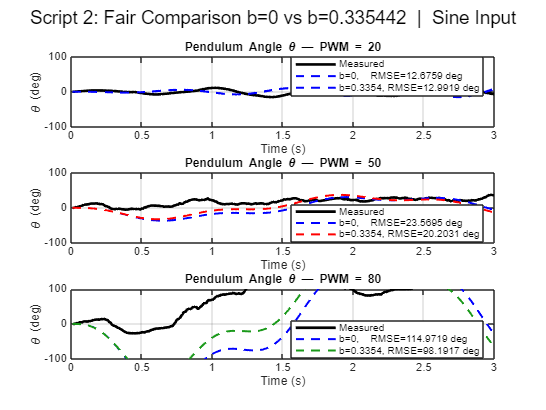

sgtitle(sprintf('Script 2: Fair Comparison b=0 vs b=%.6f  |  Sine Input', best_b));


%% =============================================
%  COST FUNCTION
%% =============================================
function total_error = cost_function_b_joint(b, p, J_true, t_meas, meas_theta_cell, Ts_sim, omega_drive)
    if b < 0
        total_error = 1e6; return;
    end

    M_total = p.m + p.M;
    L_p     = J_true + p.m * p.l^2;
    det_val = M_total * L_p - (p.m * p.l)^2;

    A = [0 1 0 0;
         0, -b*L_p/det_val,        -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  b*p.m*p.l/det_val,     (p.m*p.g*p.l*M_total)/det_val, 0];
    B = [0; L_p/det_val; 0; -p.m*p.l/det_val];
    C = [1 0 0 0; 0 0 1 0];
    D = [0; 0];

    sys_temp = ss(A, B, C, D);
    t_sim    = (t_meas(1) : Ts_sim : t_meas(end))';
    u        = sin(omega_drive * t_sim);

    total_error = 0;
    for i = 1:numel(meas_theta_cell)
        theta_meas  = meas_theta_cell{i};
        y           = lsim(sys_temp, u, t_sim);
        theta_model = interp1(t_sim, y(:,2), t_meas);

        if max(abs(theta_model)) < 1e-10
            total_error = total_error + 1e6; continue;
        end

        scale     = max(abs(theta_meas)) / max(abs(theta_model));
        error_vec = theta_meas - scale * theta_model;
        total_error = total_error + sqrt(mean(error_vec.^2));
    end
end